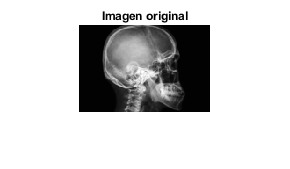

% Actividad
% Carlos Enrique Lopez Jimenez A01283855
% Genaro Gallardo Bórquez A01382459
% Claudia Esmeralda González Castillo A01411506
% Jesús Eduardo Martínez Herrera A01283785
% Mario Veccio Castro Berrones A00826824

f=imread('craneo.jpg'); % lectura de la imagen
f=double(f(:,:,1));
f=f/max(max(f));
f=imresize(f,0.15); % ajuste de la imagen
figure(1)
imshow(f,[]), title('Imagen original');

## Thresholding

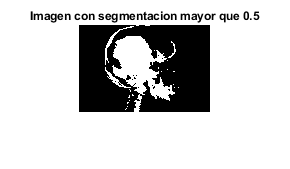

seg1 = f > 0.5; % tamaño de la segmentacion
imshow(seg1,[]), title('Imagen con segmentacion mayor que 0.5');

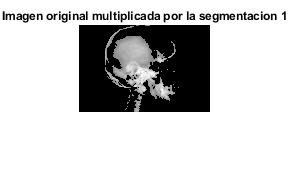

imshow(seg1.*f,[]), title('Imagen original multiplicada por la segmentacion 1');

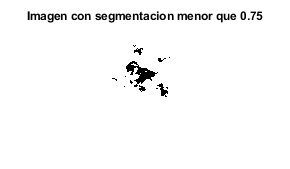

seg1 = f < 0.75; % segmentacion con parametro diferente
imshow(seg1,[]), title('Imagen con segmentacion menor que 0.75')

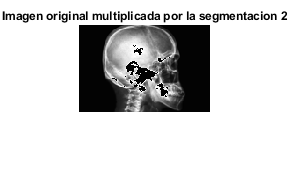

imshow(seg1.*f,[]), title('Imagen original multiplicada por la segmentacion 2');

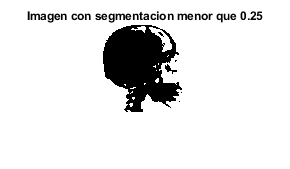

seg1 = f < 0.25; % segmentacion con parametro personal
imshow(seg1,[]), title('Imagen con segmentacion menor que 0.25')

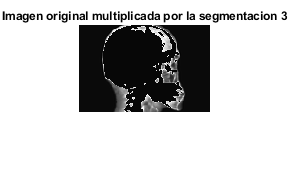

imshow(seg1.*f,[]), title('Imagen original multiplicada por la segmentacion 3');

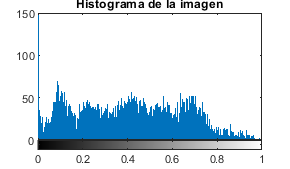

imhist(f), ylim([0 150]), title('Histograma de la imagen') % recuento del histograma y sus ubicaciones, se considera escala de grises

% Use a third threshold based on the histogram

## Otsu method

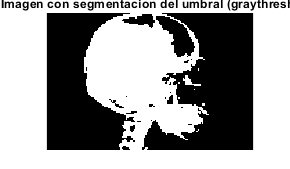

thr = graythresh(f); % se calcula el umbral global a partir de la escala de grises de la imagen
seg1 = f > thr; % segmentacion del umbral
imshow(seg1,[]), title('Imagen con segmentacion del umbral (graythresh)');

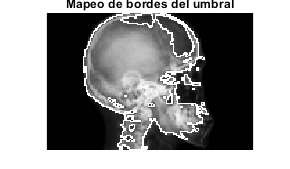

dxp=[0,1;-1,0];
dyp=[1,0;0,-1];
edgemap = abs(conv2(seg1,dxp,'same'))+abs(conv2(seg1,dyp,'same')); % mapeo de los bordes a partir de escala de grises
imshow(f+edgemap,[0,1]), title('Mapeo de bordes del umbral');


% Compare the otsu provided threshold vs the one you selected in the
% preview step.
% Do you trust the Otsu treshold? Si, se ven diferencias en cuestion de las
% tonalidades pero las figuras/segmentos que se forman son similares
% Select your own image and compute the otsu threshold

## Kmeans segmentation

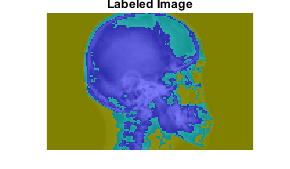

[L,Centers] = imsegkmeans(int8(255*f),3); % segmentacion de la imagen a traves de este metodo, k-means
B = labeloverlay(f,L);
imshow(B), title("Labeled Image");

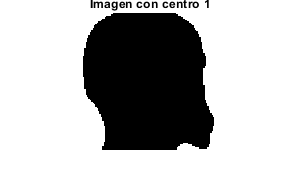

imshow(int8(255*f)<Centers(1),[]), title('Imagen con centro 1');

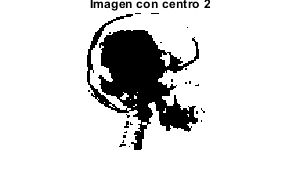

imshow(int8(255*f)<Centers(2),[]), title('Imagen con centro 2');

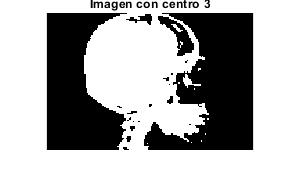

imshow(int8(255*f)>Centers(3),[]), title('Imagen con centro 3');

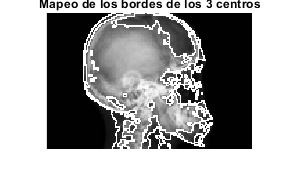

edgemap = abs(conv2(L,dxp,'same'))+abs(conv2(L,dyp,'same')); % Mapeo de los bordes
imshow(f+edgemap,[0,1]), title('Mapeo de los bordes de los 3 centros');


% Do the same procedure but now with 5 centers.
% Is the segmentation better?

## Watershed segmentation

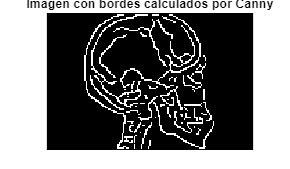

edgeC = edge(f,'Canny'); % Deteccion de bordes con metodo Canny
imshow(edgeC,[]), title('Imagen con bordes calculados por Canny');

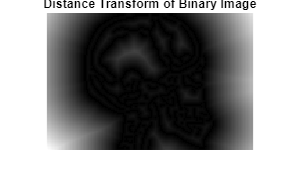

D = bwdist(edgeC); % Transformada usando metodo Euclidiano asignando numero acorde con 
% la distancia del pixel y el pixel distinto de cero mas cercano
imshow(D,[]), title('Distance Transform of Binary Image');

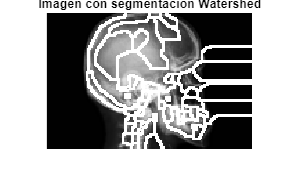

L = watershed(D); % Segmentacion de la imagen en base a claridad de los pixeles, los 
% claros se consideran altas elevaciones y los oscuros bajas elevaciones
edgemap = abs(conv2(L,dxp,'same'))+abs(conv2(L,dyp,'same')); % Mapeo de bordes watershed
imshow(f+edgemap,[0,1]), title('Imagen con segmentacion Watershed');


L(edgeC) = 0;

Display the resulting label matrix as an RGB image.

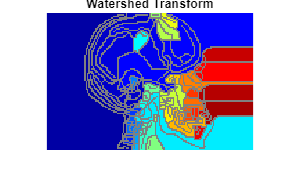

rgb = label2rgb(L,'jet',[.5 .5 .5]); % Cambio de la imagen a RGB para visualizar las regiones
% etiquetadas
imshow(rgb), title('Watershed Transform');


% provide an alterante segmentation based on a different edge detector